# Run Param_lab3_real.mlx

## Run General parameter

step_amplitude = 50;

# Simulate step 50 [deg] ss robust tracking (lab3_ss_robust_box_sim.slx ) or real

## Salva dati 50 deg ss robust tracking


t = ScopeData1.time;
tetha_h = ScopeData1.signals(1).values;  
tetha_d = ScopeData1.signals(2).values;
ref_signal = ScopeData1.signals(3).values;  
command_u =  ScopeData1.signals(4).values;  

save("ss_data_lab3_50_robust_real.mat",'t','tetha_h','tetha_d','ref_signal','command_u');



## Stampa grafico

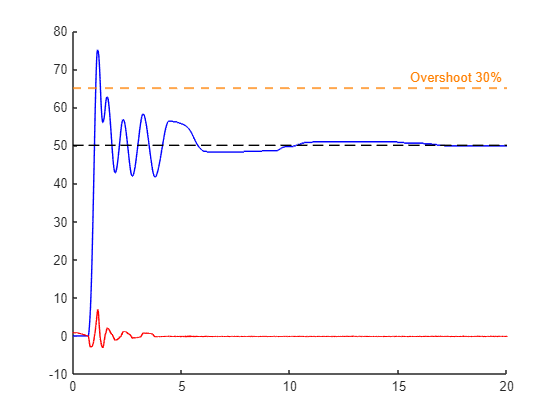


% grafico step 50 deg

load("ss_data_lab3_50_robust_real.mat");
figure;
% plot(t,ref,'k--');
yline(65, '--', 'Color', '[1, 0.5, 0]', 'LineWidth', 1.5, 'Label', 'Overshoot 30%');
hold on 
plot(t,tetha_h,'b');
plot(t,tetha_d,'r');
plot(t,ref_signal,'k--');
axis([0 20 -10 80])
hold off

#### Step response parameters


step_50_wind_up = stepinfo(tetha_h, t, 50, 'SettlingTimeThreshold', 0.05);
disp(step_50_wind_up);

         RiseTime: NaN
    TransientTime: NaN
     SettlingTime: NaN
      SettlingMin: NaN
      SettlingMax: NaN
        Overshoot: 0
       Undershoot: 0
             Peak: 38.7000
         PeakTime: 24.2590

